clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[4.770;8.820;17.257];
u31=[0.652;-0.749;0.117];
r2=[-4.349;8.820;17.257];
u32=[0.652;-0.749;0.117];
r3=[0.515;17.521;17.303];
u33=[-0.652;-0.749;-0.117];
r4=[9.634;17.521;17.303];
u34=[-0.652;-0.749;-0.117];
r5=[1.793;8.582;5.783];
u35=[-0.652;0.749;-0.117];
r6=[10.912;8.582;5.783];
u36=[-0.652;0.749;-0.117];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];

hold on
axis([0 15 0 15]);
for R3=13:-0.3:3.5%离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.5500   13.0000    1.0006


ans =     3.5500   12.7000    1.0031


ans =     3.5600   12.4000    1.0004


ans =     3.5600   12.1000    1.0033


ans =     3.5700   11.8000    1.0012


ans =     3.5700   11.5000    1.0045


ans =     3.5800   11.2000    1.0029


ans =     3.5900   10.9000    1.0017


ans =     3.6000   10.6000    1.0008


ans =     3.6100   10.3000    1.0003


ans =     3.6200   10.0000    1.0003


ans =     3.6300    9.7000    1.0009


ans =     3.6400    9.4000    1.0020


ans =     3.6500    9.1000    1.0038


ans =     3.6700    8.8000    1.0014


ans =     3.6900    8.5000    1.0000


ans =     3.7000    8.2000    1.0044


ans =     3.7300    7.9000    1.0006


ans =     3.7500    7.6000    1.0029


ans =     3.7800    7.3000    1.0023


ans =     3.8100    7.0000    1.0037


ans =     3.8500    6.7000    1.0032


ans =     3.9000    6.4000    1.0015


ans =     3.9500    6.1000    1.0035


ans =     4.0200    5.8000    1.0022


ans =     4.1000    5.5000    1.0031


ans =     4.2100    5.2000    1.0011


ans =     4.3400    4.9000    1.0026


ans =     4.5300    4.6000    1.0001


ans =     4.7800    4.3000    1.0010


ans =     5.1600    4.0000    1.0012


ans =     5.8000    3.7000    1.0008



for R1=6:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     6.0000    3.6300    1.0026


ans =     6.3000    3.5500    1.0023


ans =     6.6000    3.4800    1.0040


ans =     6.9000    3.4300    1.0020


ans =     7.2000    3.3800    1.0039


ans =     7.5000    3.3400    1.0044


ans =     7.8000    3.3100    1.0028


ans =     8.1000    3.2800    1.0033


ans =     8.4000    3.2600    1.0005


ans =     8.7000    3.2300    1.0045


ans =     9.0000    3.2100    1.0047


ans =     9.3000    3.2000    1.0006


ans =     9.6000    3.1800    1.0030


ans =     9.9000    3.1700    1.0007


ans =    10.2000    3.1500    1.0047


ans =    10.5000    3.1400    1.0039


ans =    10.8000    3.1300    1.0036


ans =    11.1000    3.1200    1.0039


ans = 1×3
   11.4000    3.1100    1.0046


ans = 1×3
   11.7000    3.1000    1.0058


ans = 1×3
   12.0000    3.1000    1.0014


ans = 1×3
   12.3000    3.0900    1.0033


ans = 1×3
   12.6000    3.0800    1.0055


ans = 1×3
   12.9000    3.0800    1.0019


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')

for R1=2:0.3:9 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans = 1×3
    2.0000    7.2500    1.0003


ans = 1×3
    2.3000    6.9700    1.0002


ans = 1×3
    2.6000    6.7000    1.0007


ans = 1×3
    2.9000    6.4400    1.0011


ans = 1×3
    3.2000    6.1900    1.0011


ans = 1×3
    3.5000    5.9400    1.0023


ans = 1×3
    3.8000    5.7000    1.0018


ans = 1×3
    4.1000    5.4600    1.0011


ans = 1×3
    4.4000    5.2100    1.0020


ans = 1×3
    4.7000    4.9600    1.0014


ans = 1×3
    5.0000    4.7000    1.0010


ans = 1×3
    5.3000    4.4300    1.0004


ans = 1×3
    5.6000    4.1400    1.0013


ans = 1×3
    5.9000    3.8400    1.0014


ans = 1×3
    6.2000    3.5300    1.0008


ans = 1×3
    6.5000    3.2000    1.0019


ans = 1×3
    6.8000    2.8700    1.0012


ans = 1×3
    7.1000    2.5300    1.0012


ans = 1×3
    7.4000    2.1900    1.0007


ans = 1×3
    7.7000    1.8500    1.0001


ans = 1×3
    8.0000    1.5000    1.0016


ans = 1×3
    8.3000    1.1600    1.0018


ans = 1×3
    8.6000    0.8300    1.0006


ans = 1×3
    8.9000    0.5000    1.0001



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')


for R1=2:0.3:9.6 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    2.0000    7.6500    1.0017


ans = 1×3
    2.3000    7.3600    1.0002


ans = 1×3
    2.6000    7.0700    1.0010


ans = 1×3
    2.9000    6.7900    1.0017


ans = 1×3
    3.2000    6.5200    1.0018


ans = 1×3
    3.5000    6.2600    1.0012


ans = 1×3
    3.8000    6.0000    1.0015


ans = 1×3
    4.1000    5.7500    1.0001


ans = 1×3
    4.4000    5.4900    1.0008


ans = 1×3
    4.7000    5.2300    1.0009


ans = 1×3
    5.0000    4.9700    1.0000


ans = 1×3
    5.3000    4.6900    1.0018


ans = 1×3
    5.6000    4.4100    1.0018


ans = 1×3
    5.9000    4.1200    1.0019


ans = 1×3
    6.2000    3.8300    1.0001


ans = 1×3
    6.5000    3.5200    1.0005


ans = 1×3
    6.8000    3.2000    1.0013


ans = 1×3
    7.1000    2.8800    1.0010


ans = 1×3
    7.4000    2.5500    1.0019


ans = 1×3
    7.7000    2.2300    1.0005


ans = 1×3
    8.0000    1.9000    1.0009


ans = 1×3
    8.3000    1.5700    1.0015


ans = 1×3
    8.6000    1.2500    1.0003


ans = 1×3
    8.9000    0.9200    1.0014


ans = 1×3
    9.2000    0.6000    1.0009


ans = 1×3
    9.5000    0.2800    1.0008



plot(x3,y3,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')


for R3=2:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    9.0600    2.0000    1.0003


ans = 1×3
    7.7500    2.3000    1.0002


ans = 1×3
    7.1300    2.6000    1.0003


ans = 1×3
    6.7700    2.9000    1.0007


ans = 1×3
    6.5400    3.2000    1.0006


ans = 1×3
    6.3800    3.5000    1.0009


ans = 1×3
    6.2600    3.8000    1.0022


ans = 1×3
    6.1800    4.1000    1.0004


ans = 1×3
    6.1100    4.4000    1.0013


ans = 1×3
    6.0600    4.7000    1.0004


ans = 1×3
    6.0100    5.0000    1.0026


ans = 1×3
    5.9800    5.3000    1.0011


ans = 1×3
    5.9500    5.6000    1.0014


ans = 1×3
    5.9300    5.9000    1.0001


ans = 1×3
    5.9000    6.2000    1.0030


ans = 1×3
    5.8900    6.5000    1.0006


ans = 1×3
    5.8700    6.8000    1.0021


ans = 1×3
    5.8600    7.1000    1.0010


ans = 1×3
    5.8500    7.4000    1.0005


ans = 1×3
    5.8400    7.7000    1.0004


ans = 1×3
    5.8300    8.0000    1.0007


ans = 1×3
    5.8200    8.3000    1.0013


ans = 1×3
    5.8100    8.6000    1.0023


ans = 1×3
    5.8100    8.9000    1.0001


ans = 1×3
    5.8000    9.2000    1.0015


ans = 1×3
    5.7900    9.5000    1.0031


ans = 1×3
    5.7900    9.8000    1.0015


ans = 1×3
    5.7900   10.1000    1.0000


ans = 1×3
    5.7800   10.4000    1.0020


ans = 1×3
    5.7800   10.7000    1.0008


ans = 1×3
    5.7700   11.0000    1.0031


ans = 1×3
    5.7700   11.3000    1.0020


ans = 1×3
    5.7700   11.6000    1.0011


ans = 1×3
    5.7700   11.9000    1.0002


ans = 1×3
    5.7600   12.2000    1.0028


ans = 1×3
    5.7600   12.5000    1.0020


ans = 1×3
    5.7600   12.8000    1.0013



plot(x4,y4,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-5')


for R3=2:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    9.0100    2.0000    1.0002


ans = 1×3
    8.0700    2.3000    1.0003


ans = 1×3
    7.5800    2.6000    1.0003


ans = 1×3
    7.2800    2.9000    1.0009


ans = 1×3
    7.0800    3.2000    1.0017


ans = 1×3
    6.9400    3.5000    1.0022


ans = 1×3
    6.8400    3.8000    1.0019


ans = 1×3
    6.7700    4.1000    1.0002


ans = 1×3
    6.7100    4.4000    1.0002


ans = 1×3
    6.6600    4.7000    1.0008


ans = 1×3
    6.6200    5.0000    1.0012


ans = 1×3
    6.5900    5.3000    1.0007


ans = 1×3
    6.5600    5.6000    1.0018


ans = 1×3
    6.5400    5.9000    1.0011


ans = 1×3
    6.5200    6.2000    1.0014


ans = 1×3
    6.5000    6.5000    1.0026


ans = 1×3
    6.4900    6.8000    1.0014


ans = 1×3
    6.4800    7.1000    1.0007


ans = 1×3
    6.4700    7.4000    1.0005


ans = 1×3
    6.4600    7.7000    1.0007


ans = 1×3
    6.4500    8.0000    1.0012


ans = 1×3
    6.4400    8.3000    1.0020


ans = 1×3
    6.4300    8.6000    1.0030


ans = 1×3
    6.4300    8.9000    1.0012


ans = 1×3
    6.4200    9.2000    1.0026


ans = 1×3
    6.4200    9.5000    1.0011


ans = 1×3
    6.4100    9.8000    1.0028


ans = 1×3
    6.4100   10.1000    1.0016


ans = 1×3
    6.4100   10.4000    1.0005


ans = 1×3
    6.4000   10.7000    1.0025


ans = 1×3
    6.4000   11.0000    1.0016


ans = 1×3
    6.4000   11.3000    1.0007


ans = 1×3
    6.3900   11.6000    1.0030


ans = 1×3
    6.3900   11.9000    1.0022


ans = 1×3
    6.3900   12.2000    1.0015


ans = 1×3
    6.3900   12.5000    1.0009


ans = 1×3
    6.3900   12.8000    1.0003


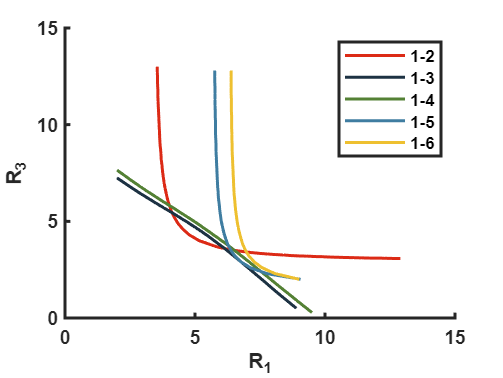


plot(x5,y5,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5,'DisplayName','1-6')




set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
